Данные задачи

clear; clc;
syms u v  e f g h;
F1 = e*u.*(1-u) - (  u.*v)/(1+g*u);
F2 = -f*v      + (h*u.*v)/(1+g*u);
F = [F1;F2]

$$F = \left(\begin{array}{c} -e\,u\,\left(u-1\right)-\frac{u\,v}{g\,u+1}\\ \frac{h\,u\,v}{g\,u+1}-f\,v \end{array}\right)$$

%determine parameters of interest
parameters = [e h];
F = subs(F,[f g], [1 1])

$$F = \left(\begin{array}{c} -e\,u\,\left(u-1\right)-\frac{u\,v}{u+1}\\ \frac{h\,u\,v}{u+1}-v \end{array}\right)$$

Поиск неподвижных точек

eqn = 0 == F;
vars = [u,v];
[solu, solv] = solve(eqn,vars);
solutions = [solu solv]

$$solutions = \left(\begin{array}{cc} 0 & 0\\ 1 & 0\\ \frac{1}{h-1} & -\frac{2\,e\,h-e\,h^{2}}{h^{2}-2\,h+1} \end{array}\right)$$

Характер неподвижных точек

   Первая точка

k = 1;
static_point = solutions(k,:)

$$static\_point = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$


[tr, dt] = get_trace_n_determinant(F,vars,static_point);

$$new\_vars = \left(\begin{array}{cc} x & y \end{array}\right)$$

$$substitution = \left(\begin{array}{cc} x & y \end{array}\right)$$

$$F\_new = \left(\begin{array}{c} -e\,x\,\left(x-1\right)-\frac{x\,y}{x+1}\\ \frac{h\,x\,y}{x+1}-y \end{array}\right)$$

$$Jac = \left(\begin{array}{cc} \frac{x\,y}{{\left(x+1\right)}^{2}}-e\,x-e\,\left(x-1\right)-\frac{y}{x+1} & -\frac{x}{x+1}\\ \frac{h\,y}{x+1}-\frac{h\,x\,y}{{\left(x+1\right)}^{2}} & \frac{h\,x}{x+1}-1 \end{array}\right)$$

$$Jac0 = \left(\begin{array}{cc} e & 0\\ 0 & -1 \end{array}\right)$$

$$tr = e-1$$

$$dt = -e$$

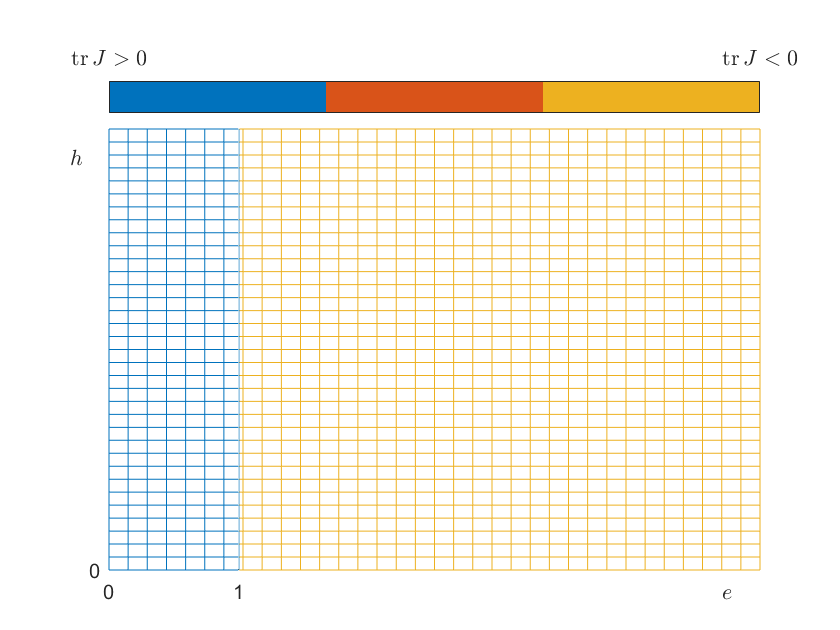

    sign_map(tr,   [0 1],0,'$\mathop{\mathrm{tr}}J > 0$','$\mathop{\mathrm{tr}}J < 0$');
    exportgraphics(gcf,'pictures/stp1/trJ.png');

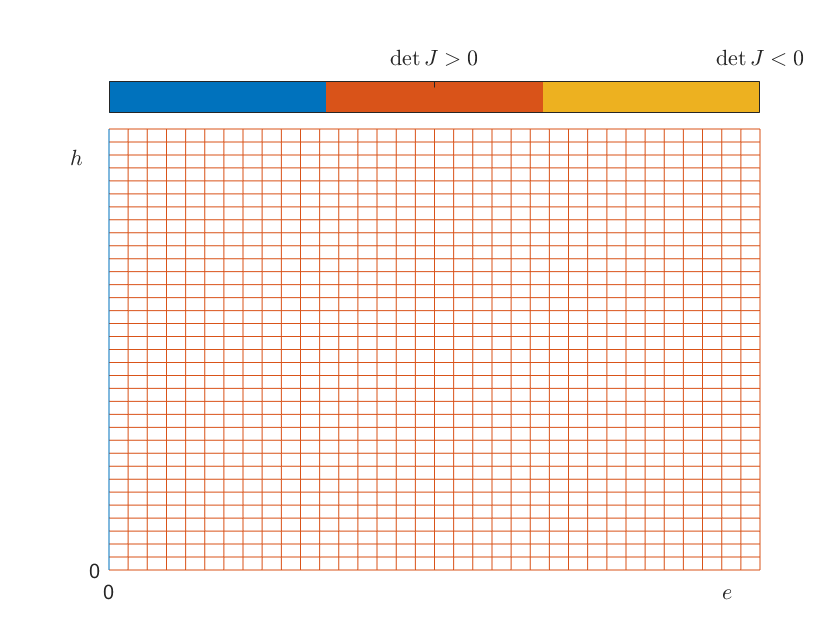

    
    sign_map(dt,       0,0,'$\det J > 0$','$\det J < 0$');
    exportgraphics(gcf,'pictures/stp1/detJ.pdf');

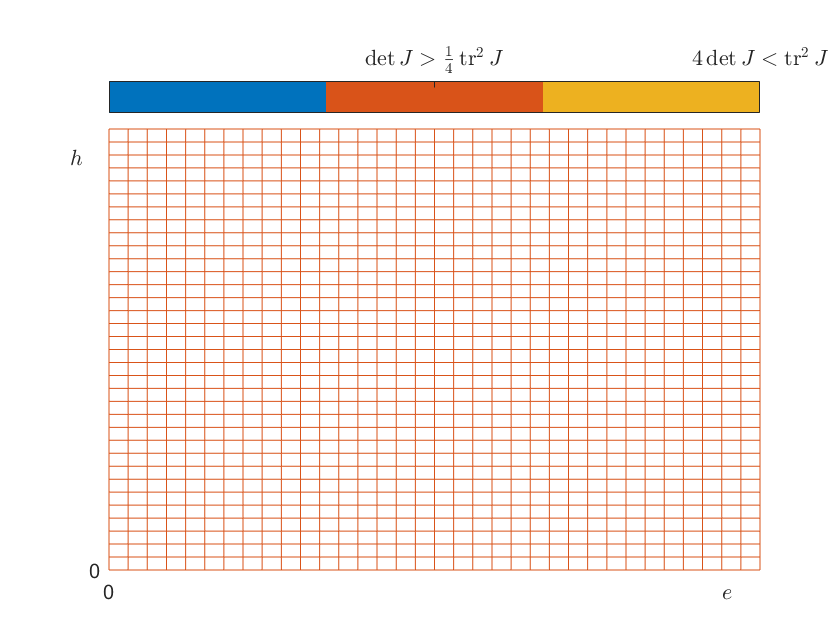

    
    sign_map(4*dt-tr^2,0,0,'$\det J > \frac{1}{4}\mathop{\mathrm{tr}}^2 J$','$4\det J < \mathop{\mathrm{tr}}^2 J$');
    exportgraphics(gcf,'pictures/stp1/trJdetJ.pdf');

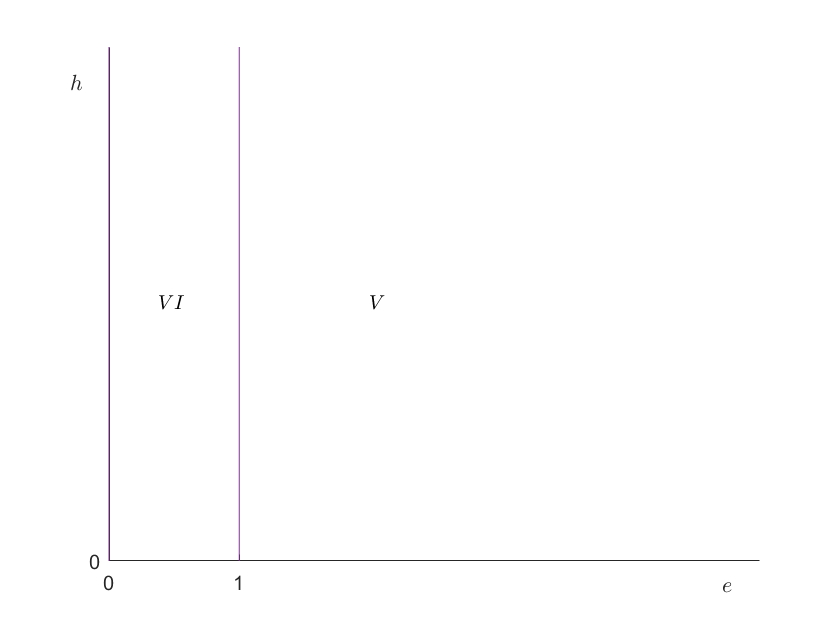

    lim = 5;
    stp_parametric_portrait(tr,dt,lim, [0 1], 0);
        hold on;
        text(0.075*lim, 0.5*lim, '$VI$','Interpreter','latex');
        text(0.4  *lim, 0.5*lim, '$V$' ,'Interpreter','latex');
        hold off;
    exportgraphics(gcf,'pictures/stp1/stability_portrait.png');

Вторая точка

k = 2

k = 2

static_point = solutions(k,:)

$$static\_point = \left(\begin{array}{cc} 1 & 0 \end{array}\right)$$


[tr, dt] = get_trace_n_determinant(F,vars,static_point);

$$new\_vars = \left(\begin{array}{cc} x & y \end{array}\right)$$

$$substitution = \left(\begin{array}{cc} x+1 & y \end{array}\right)$$

$$F\_new = \left(\begin{array}{c} -e\,x\,\left(x+1\right)-\frac{y\,\left(x+1\right)}{x+2}\\ \frac{h\,y\,\left(x+1\right)}{x+2}-y \end{array}\right)$$

$$Jac = \left(\begin{array}{cc} \frac{y\,\left(x+1\right)}{{\left(x+2\right)}^{2}}-e\,x-e\,\left(x+1\right)-\frac{y}{x+2} & -\frac{x+1}{x+2}\\ \frac{h\,y}{x+2}-\frac{h\,y\,\left(x+1\right)}{{\left(x+2\right)}^{2}} & \frac{h\,\left(x+1\right)}{x+2}-1 \end{array}\right)$$

$$Jac0 = \left(\begin{array}{cc} -e & -\frac{1}{2}\\ 0 & \frac{h}{2}-1 \end{array}\right)$$

$$tr = \frac{h}{2}-e-1$$

$$dt = -\frac{e\,\left(h-2\right)}{2}$$

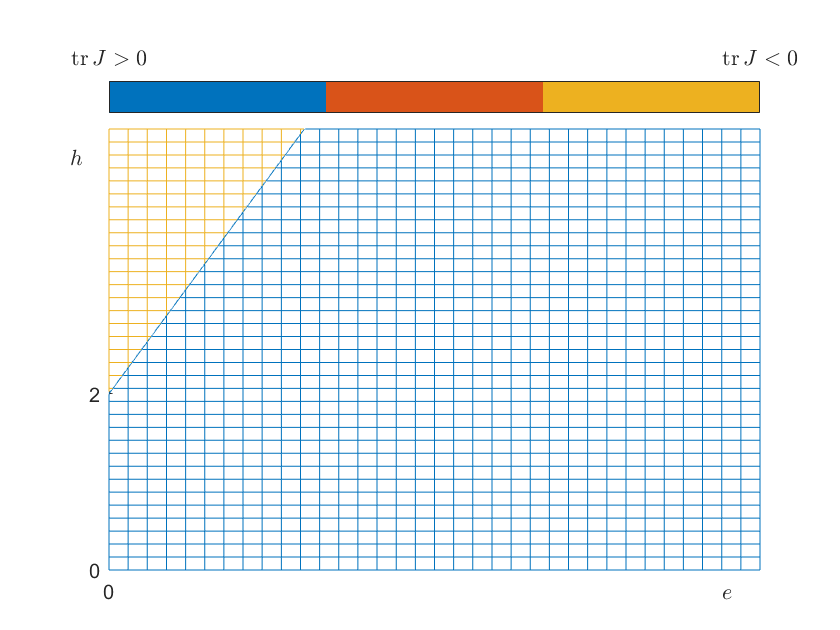

    sign_map(tr,       0,[0 2],'$\mathop{\mathrm{tr}}J > 0$','$\mathop{\mathrm{tr}}J < 0$');
    exportgraphics(gcf,'pictures/stp2/trJ.png');

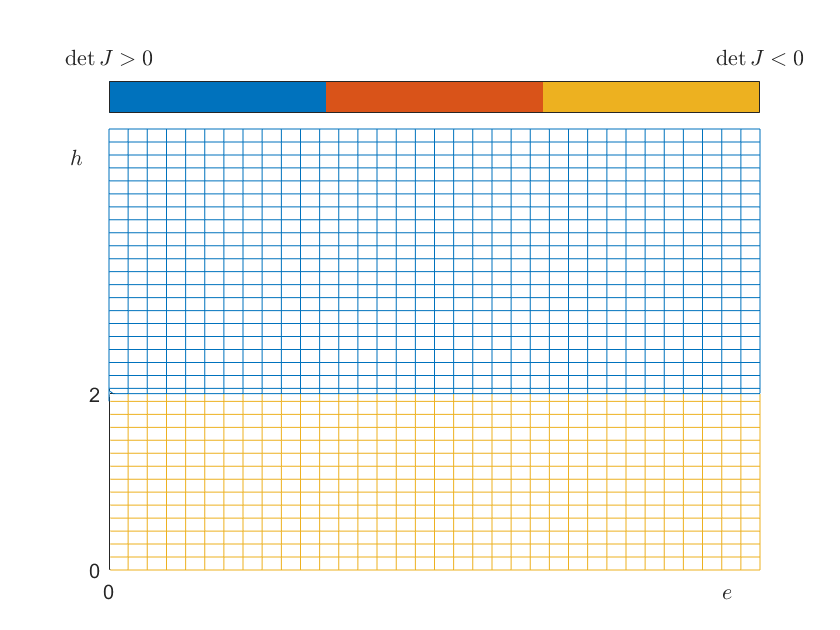

    sign_map(dt,       0,[0 2],'$\det J > 0$','$\det J < 0$');
    exportgraphics(gcf,'pictures/stp2/detJ.png');

    sign_map(4*dt-tr^2,0,0,'$\det J > \frac{1}{4}\mathop{\mathrm{tr}}^2 J$','$4\det J < \mathop{\mathrm{tr}}^2 J$');
    exportgraphics(gcf,'pictures/stp2/trJdetJ.png');

    line2 = isolate(tr == 0, h)

$$line2 = h=2\,e+2$$

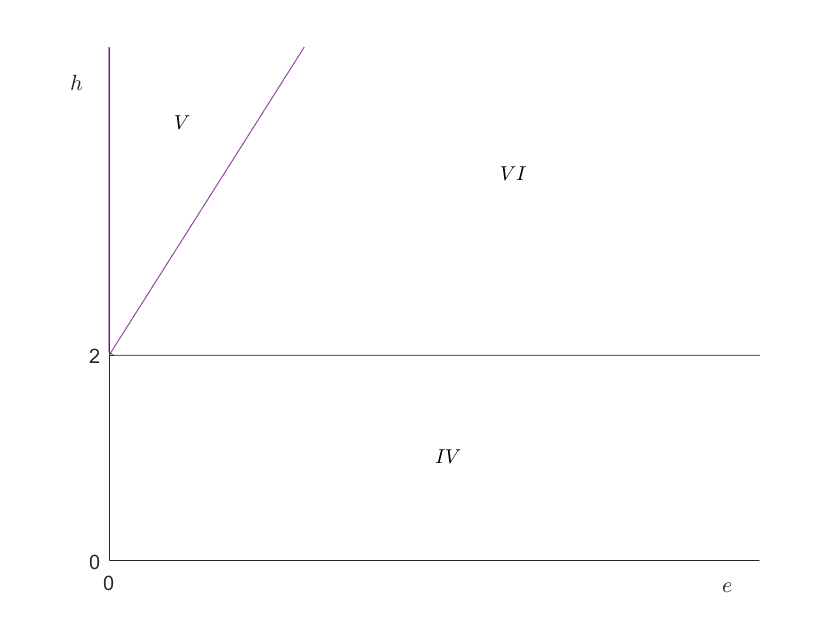

    lim = 5;
    stp_parametric_portrait(tr,dt,lim, 0, [0 2]);
        hold on;
        text(0.5 *lim, 1,   '$IV$','Interpreter','latex');
        text(0.6*lim, 3.75, '$VI$','Interpreter','latex');
        text(0.1*lim, 4.25,'$V$' ,'Interpreter','latex');
        hold off;
    exportgraphics(gcf,'pictures/stp2/stability_portrait.png');

Третья точка

k = 3

k = 3

static_point = solutions(k,:)

$$static\_point = \left(\begin{array}{cc} \frac{1}{h-1} & -\frac{2\,e\,h-e\,h^{2}}{h^{2}-2\,h+1} \end{array}\right)$$

NB! Неподвижная точка $\left(\begin{array}{cc} \frac{1}{h-1} & -\frac{2\,e\,h-e\,h^2}{h^2-2\,h+1} \end{array}\right)$ не принаделижит фазовому пространству, при $h < 2$.

subs(static_point,h,2)

$$ans = \left(\begin{array}{cc} 1 & 0 \end{array}\right)$$

При h = 2 н.т. (3) сливается с н.т. (2)

[tr, dt] = get_trace_n_determinant(F,vars,static_point);

$$new\_vars = \left(\begin{array}{cc} x & y \end{array}\right)$$

$$substitution = \left(\begin{array}{cc} x+\frac{1}{h-1} & y-\frac{2\,e\,h-e\,h^{2}}{h^{2}-2\,h+1} \end{array}\right)$$

$$F\_new = \begin{array}{l} \left(\begin{array}{c} -\frac{\left(y-\sigma_{1}\right)\,\left(x+\frac{1}{h-1}\right)}{x+\frac{1}{h-1}+1}-e\,\left(x+\frac{1}{h-1}\right)\,\left(x+\frac{1}{h-1}-1\right)\\ \sigma_{1}-y+\frac{h\,\left(y-\sigma_{1}\right)\,\left(x+\frac{1}{h-1}\right)}{x+\frac{1}{h-1}+1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{2\,e\,h-e\,h^{2}}{h^{2}-2\,h+1} \end{array}$$

$$Jac = \begin{array}{l} \left(\begin{array}{cc} \frac{\sigma_{1}\,\sigma_{3}}{{\sigma_{2}}^{2}}-e\,\sigma_{3}-e\,\left(x+\frac{1}{h-1}-1\right)-\frac{\sigma_{1}}{\sigma_{2}} & -\frac{\sigma_{3}}{\sigma_{2}}\\ \frac{h\,\sigma_{1}}{\sigma_{2}}-\frac{h\,\sigma_{1}\,\sigma_{3}}{{\sigma_{2}}^{2}} & \frac{h\,\sigma_{3}}{\sigma_{2}}-1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=y-\frac{2\,e\,h-e\,h^{2}}{h^{2}-2\,h+1}\\ \sigma_{2}=x+\frac{1}{h-1}+1\\ \sigma_{3}=x+\frac{1}{h-1} \end{array}$$

$$Jac0 = \begin{array}{l} \left(\begin{array}{cc} \frac{\sigma_{1}}{\sigma_{3}}-\frac{e}{h-1}-e\,\left(\frac{1}{h-1}-1\right)-\frac{\sigma_{1}}{\sigma_{2}} & -\frac{1}{\sigma_{4}\,\left(h-1\right)}\\ \frac{h\,\sigma_{1}}{\sigma_{2}}-\frac{h\,\sigma_{1}}{\sigma_{3}} & \frac{h}{\sigma_{4}\,\left(h-1\right)}-1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,e\,h-e\,h^{2}\\ \sigma_{2}={\sigma_{4}}^{2}\,\left(h-1\right)\,\left(h^{2}-2\,h+1\right)\\ \sigma_{3}=\sigma_{4}\,\left(h^{2}-2\,h+1\right)\\ \sigma_{4}=\frac{1}{h-1}+1 \end{array}$$

$$tr = \begin{array}{l} \frac{2\,e\,h-e\,h^{2}}{\sigma_{1}\,\left(h^{2}-2\,h+1\right)}-\frac{e}{h-1}-e\,\left(\frac{1}{h-1}-1\right)+\frac{h}{\sigma_{1}\,\left(h-1\right)}-\frac{2\,e\,h-e\,h^{2}}{{\sigma_{1}}^{2}\,\left(h-1\right)\,\left(h^{2}-2\,h+1\right)}-1\\ \mathrm{where}\\ \sigma_{1}=\frac{1}{h-1}+1 \end{array}$$

$$dt = -\frac{2\,e-e\,h}{h}$$

line3 = isolate(tr^2 == 4*dt,h)

$$line3 = h=\frac{\sqrt{2}\,\sqrt{\sqrt{4\,e+1}+1}}{2}+1$$

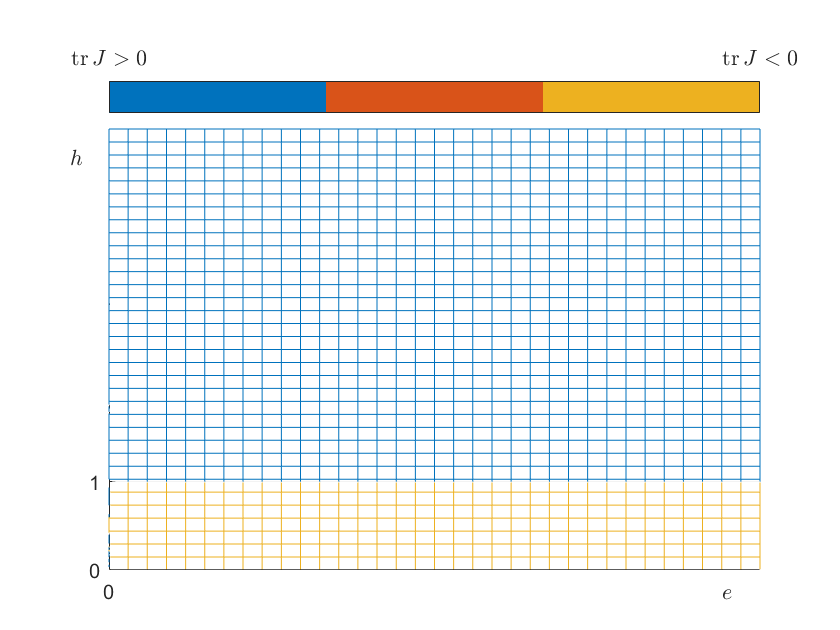

    sign_map(tr,       0,[0 1],'$\mathop{\mathrm{tr}}J > 0$','$\mathop{\mathrm{tr}}J < 0$'); 
    exportgraphics(gcf,'pictures/stp3/trJ.png');

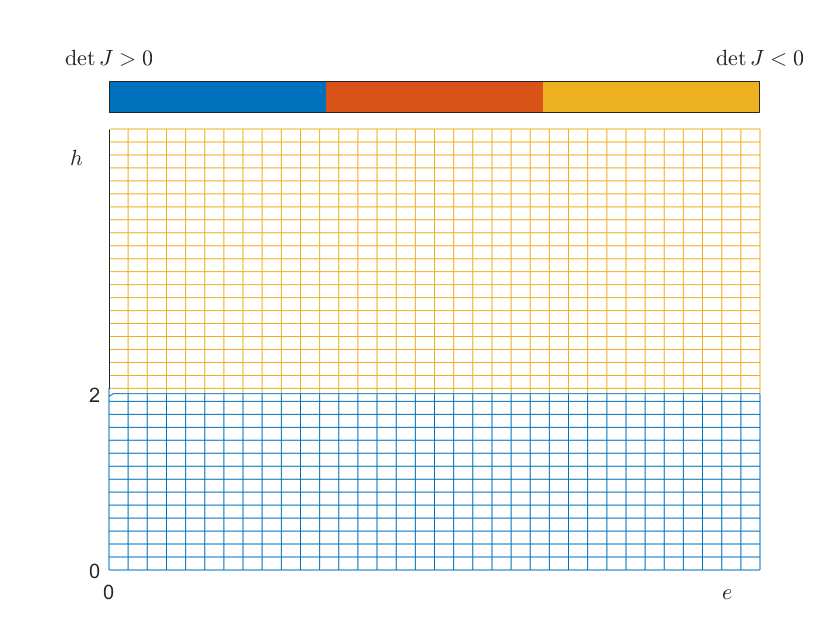

    
    sign_map(dt,       0,[0 2],'$\det J > 0$','$\det J < 0$'); 
    exportgraphics(gcf,'pictures/stp3/detJ.png');

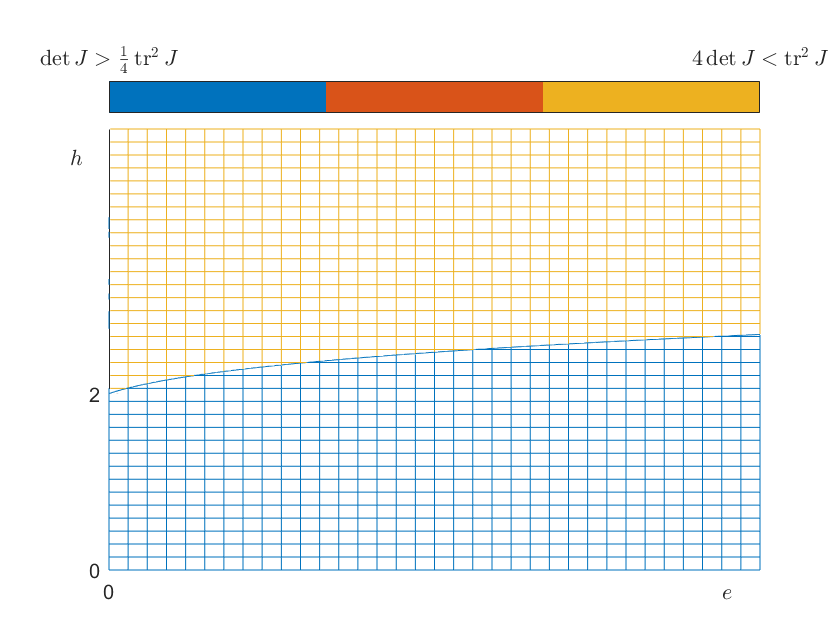

    
    sign_map(4*dt-tr^2,0,[0 2],'$\det J > \frac{1}{4}\mathop{\mathrm{tr}}^2 J$','$4\det J < \mathop{\mathrm{tr}}^2 J$');
    exportgraphics(gcf,'pictures/stp3/trJdetJ.png');

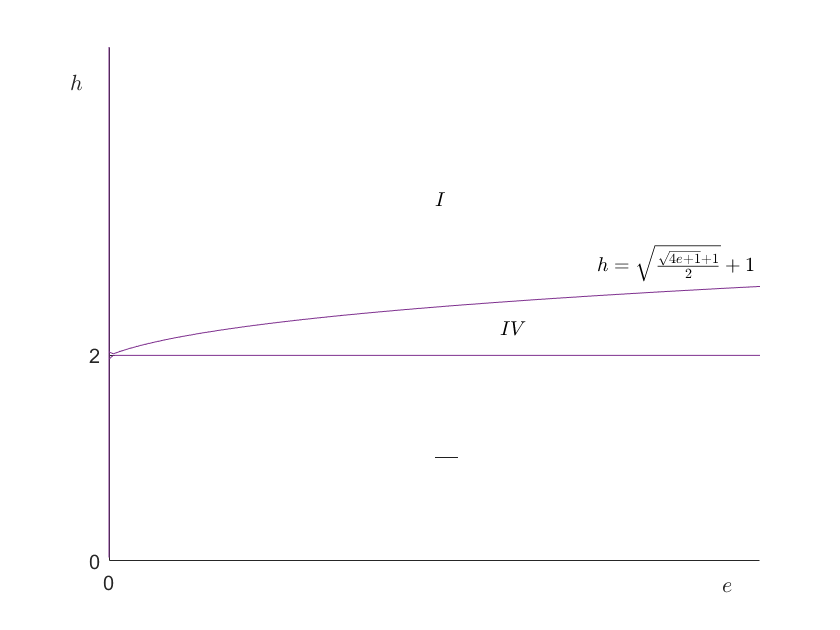

    lim = 5;
    stp_parametric_portrait(tr,dt,lim, 0, [0 2]);
        hold on;
        text(0.5 *lim, 1,  '\textbf{---}'  ,'Interpreter','latex');
        text(0.6*lim, 2.25,  '$IV$'  ,'Interpreter','latex');
        text(0.5 *lim, 3.5,'$I$'  ,'Interpreter','latex');
        text(0.75 *lim, 2.9,'$h = \sqrt{\frac{\sqrt{4e+1}+1}{2}} + 1$' ,'Interpreter','latex');
        hold off;
    exportgraphics(gcf,'pictures/stp3/stability_portrait.png'); 

Параметрический портрет системы    

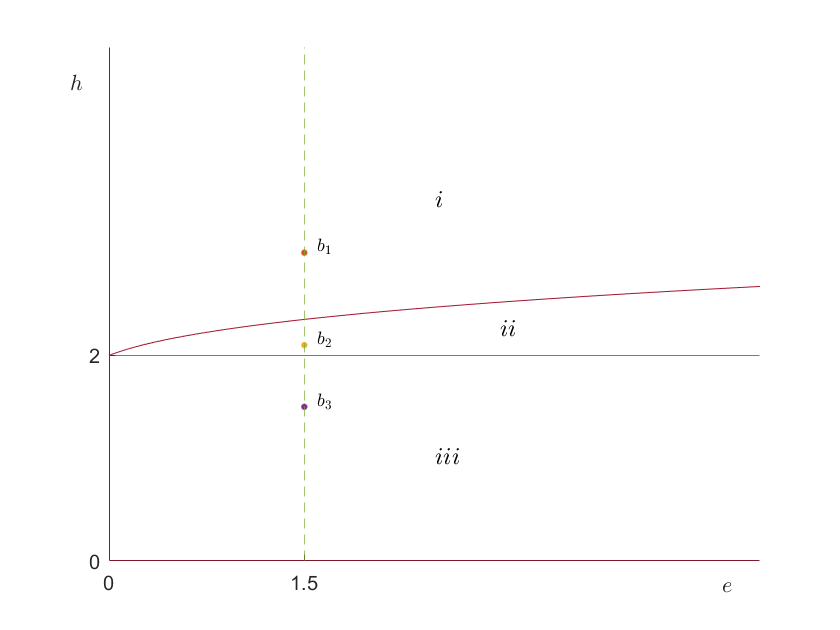

    lim = 5;
    figure;
    ax = axes;
    hold on; 
        ax.XLim  = [0 lim]; ax.YLim = [0 lim];
        X = ax.XLim; Y = ax.YLim;
        ax.XTick = [0 1.5]; ax.YTick = [0 2];
        ax.XLabel.Interpreter = 'latex'; ax.YLabel.Interpreter = 'latex';
        ax.XLabel.String = '$e$'; ax.YLabel.String = '$h$';
        ax.XLabel.Position = [0.95*X(2) -0.025*Y(2)]; ax.YLabel.Position = [-0.05*X(2) 0.9*Y(2)];
        ax.YLabel.Rotation = 0;
        
        xline(0,'Color','#A2142F'); yline(0,'Color','#A2142F');
        yline(2,'Color','#A2142F');
        fimplicit(line3,'Color','#A2142F');
        
        text(0.5 *lim, 1,  '$iii$'  ,'Interpreter','latex','FontSize',12);
        text(0.6*lim, 2.25,  '$ii$'  ,'Interpreter','latex','FontSize',12);
        text(0.5 *lim, 3.5,'$i$'  ,'Interpreter','latex','FontSize',12);
        
        xline(1.5,'Color','#77AC30','LineStyle','--');
        plot(1.5, 3,   'Marker','.','MarkerSize',10);
        plot(1.5, 2.1, 'Marker','.','MarkerSize',10);
        plot(1.5, 1.5, 'Marker','.','MarkerSize',10);
        
        text(1.6, 3.05,  '$b_1$'  ,'Interpreter','latex','FontSize',9);
        text(1.6, 2.15,'$b_2$'  ,'Interpreter','latex','FontSize',9);
        text(1.6, 1.55,'$b_3$'  ,'Interpreter','latex','FontSize',9);
        
   hold off;

exportgraphics(gcf,'pictures\phase_portraits\parametric_portrait.png');

Фазовый портрет i(k=3 -- устойчивый фокус)

fix_params = [1.5 3]; grd = 0.01:0.08:2.01;

stable_point = subs(solutions(3,:), parameters, fix_params)

$$stable\_point = \left(\begin{array}{cc} \frac{1}{2} & \frac{9}{8} \end{array}\right)$$

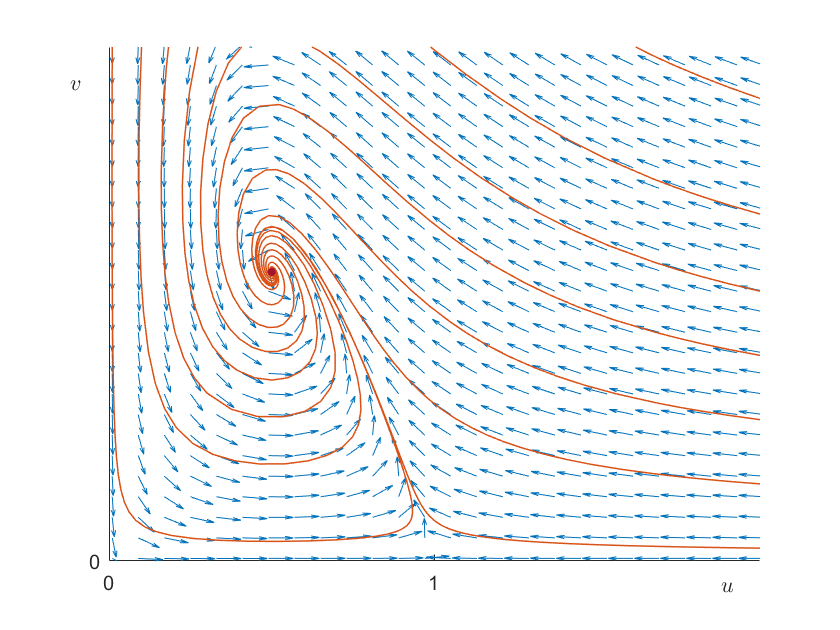


Ffix = subs(F,parameters, fix_params);

X0 = [2.00 2.00 2.00 2.00 2.00 2.00 2.00 0.10 0.01 ; 
      0.05 0.30 0.55 0.80 1.05 1.35 1.80 2.00 2.00];
  
figure;
add_phase_portrait_plot(Ffix,vars,grd,fix_params(1),fix_params(2),X0,stable_point);

exportgraphics(gcf,'pictures\phase_portraits\i.pdf');

Фазовый портерт ii (k=3 -- устойчивый узел)

fix_params = [1.5 2.1]; grd = 0.01:0.08:2.01;

stable_point = subs(solutions(3,:), parameters, fix_params)

$$stable\_point = \left(\begin{array}{cc} \frac{10}{11} & \frac{63}{242} \end{array}\right)$$

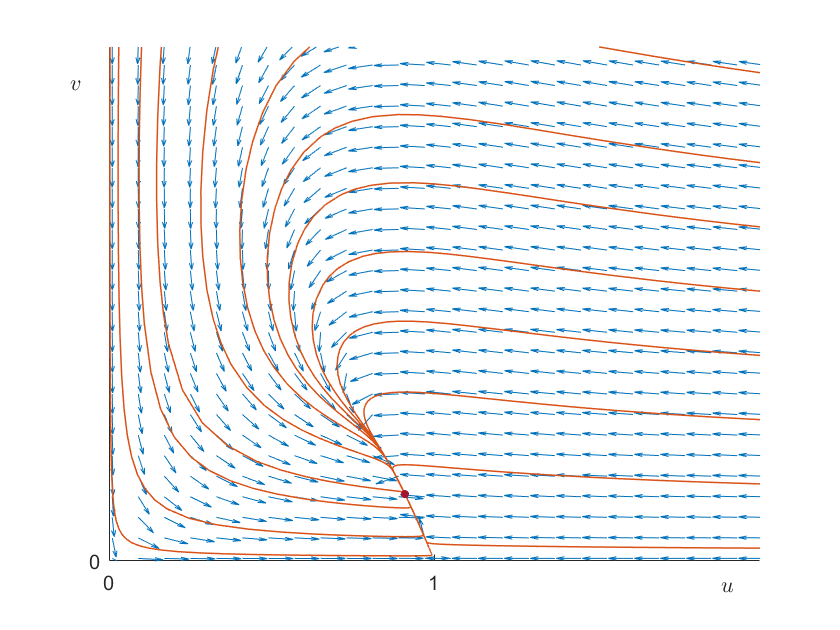


Ffix = subs(F,parameters, fix_params);

X0 = [2.00 2.00 2.00 2.00 2.00 2.00 2.00 2.00 2.00 2.00 0.10 0.03 0.003; 
      0.05 0.30 0.55 0.80 1.05 1.30 1.55 1.90 2.50 3.50 2.00 2.00 2.000];
  
figure;
add_phase_portrait_plot(Ffix,vars,grd,fix_params(1),fix_params(2),X0, stable_point);

exportgraphics(gcf,'pictures\phase_portraits\ii.pdf');

Фазовый портет iii (k=2 -- устойчивый узел)

fix_params = [1.5 1.5]; grd = 0.01:0.08:2.01;

stable_point = solutions(2,:)

$$stable\_point = \left(\begin{array}{cc} 1 & 0 \end{array}\right)$$

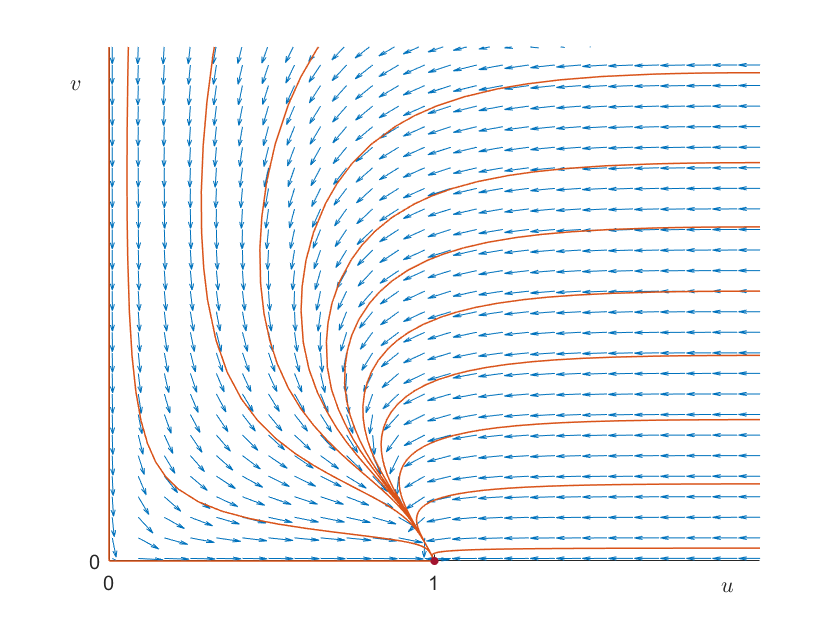


Ffix = subs(F,parameters, fix_params);

X0 = [2.00 2.00 2.00 2.00 2.00 2.00 2.00 2.00 2.00 2.00 2.00 2.00; 
      0.05 0.30 0.55 0.80 1.05 1.30 1.55 1.90 2.50 3.50 6.00 50.0];
  
figure;
add_phase_portrait_plot(Ffix,vars,grd,fix_params(1),fix_params(2),X0, stable_point);

exportgraphics(gcf,'pictures\phase_portraits\iii.pdf');

Дивергенция векторного поля (частный случай)

divF = divergence(F,vars);
[N D] = numden(divF)

$$N = e-2\,u-v+h\,u-3\,e\,u^{2}-2\,e\,u^{3}+h\,u^{2}-u^{2}-1$$

$$D = {\left(u+1\right)}^{2}$$

divF = N/D

$$divF = -\frac{2\,u-e+v-h\,u+3\,e\,u^{2}+2\,e\,u^{3}-h\,u^{2}+u^{2}+1}{{\left(u+1\right)}^{2}}$$

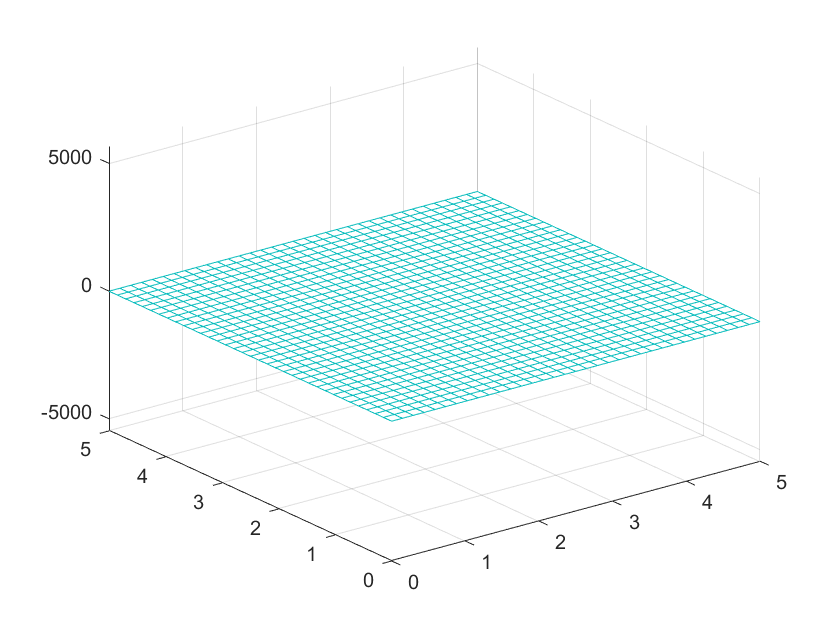

fmesh(subs(divF,parameters,[1 1])); ax = gca; ax.XLim = [0 Inf]; ax.YLim = [0 Inf];

Дополнительные рисунки

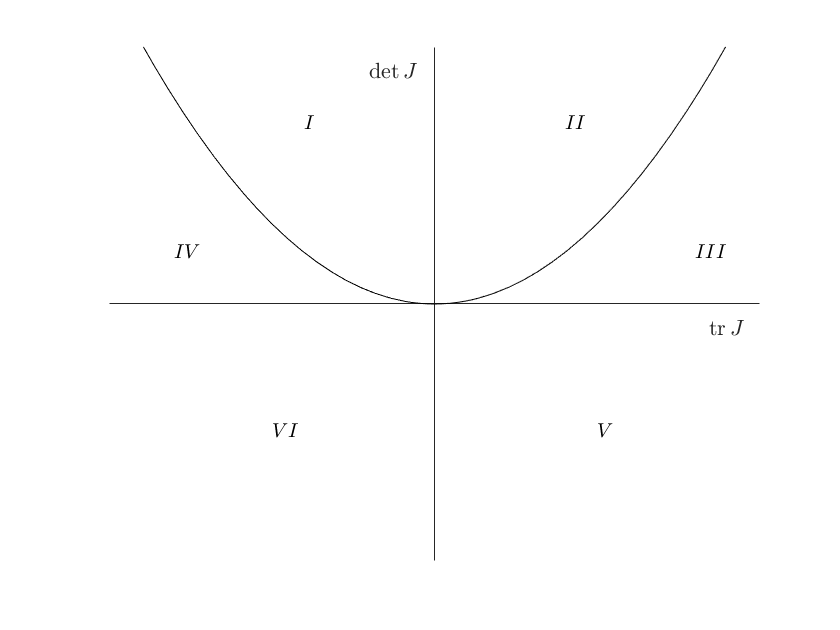

fplot(@(x) 0.25*x.^2,'Color','#000000');
ax = gca;
    t = 5;
    ax.XLim = [-t t]; ax.YLim = [-t t];
    ax.XTick = []; ax.YTick = [];
    ax.XAxisLocation = 'origin'; ax.YAxisLocation = 'origin'; ax.Box = "off";
    ax.XLabel.Interpreter = 'latex'; ax.YLabel.Interpreter = 'latex';
    ax.XLabel.Position = [0.95*t -0.15*t]; ax.YLabel.Position = [-0.2*t 0.95*t];
    ax.YLabel.Rotation = 0;
    ax.XLabel.String = '$\mathop{\mathrm{tr}}J$'; ax.YLabel.String = '$\det J$';
text(-0.4*t, 0.7*t,'$I$'  ,'Interpreter','latex');
text( 0.4*t, 0.7*t,'$II$' ,'Interpreter','latex');
text( 0.8*t, 0.2*t,'$III$','Interpreter','latex');
text(-0.8*t, 0.2*t,'$IV$' ,'Interpreter','latex');
text( 0.5*t,-0.5*t,'$V$'  ,'Interpreter','latex');
text(-0.5*t,-0.5*t,'$VI$' ,'Interpreter','latex');

exportgraphics(gcf,'pictures\stabilities.pdf');

Вспомогательные функции

function res = odefun(t,x,e,f,g,h)
    res =  [e*x(1).*(1-x(1)) - (  x(1).*x(2))./(1+g*x(1));
            -f*x(2)          + (h*x(1).*x(2))./(1+g*x(1))];
end

function [tr, dt] = get_trace_n_determinant(F,vars,static_point)
    syms x y; %substitution 
    new_vars = [x y]
        %x = u - u* => u = x + u*; \dot u = f(x+u*); v~--- analogously
    substitution = new_vars + static_point
    F_new = subs(F,vars, substitution)
    Jac = jacobian(F_new,new_vars)
    Jac0 = subs(Jac,[x y], [0 0])
    
    tr = trace(Jac0)
    dt = det(Jac0)
end

function sign_map(func, x_ticks,y_ticks, label_lz,label_gz)
             fmesh(func > 0); 
    hold on; fimplicit(func == 0); hold off; 
    ax = gca; 
        ax.XLim(1) = 0; ax.YLim(1) = 0;
        X = ax.XLim; Y = ax.YLim;
        ax.XTick = x_ticks; ax.YTick = y_ticks;
        ax.XLabel.Interpreter = 'latex'; ax.YLabel.Interpreter = 'latex';
        ax.XLabel.String = '$e$'; ax.YLabel.String = '$h$';
        ax.XLabel.Position = [0.95*X(2) -0.025*Y(2)]; ax.YLabel.Position = [-0.05*X(2) 0.9*Y(2)];
        ax.YLabel.Rotation = 0;
    colormap(lines(3));
    cb = colorbar('Ticks',[0 1],'TickLabels',{label_lz,label_gz},'TickLabelInterpreter',"latex");
    cb.Location = 'northoutside';
    cb.FontSize = 11;
    view([0 90]);
end

function stp_parametric_portrait(tr,dt,lim, x_ticks,y_ticks)
    figure;
    ax = axes;
    hold on; 
        ax.XLim  = [0 lim]; ax.YLim = [0 lim];
        X = ax.XLim; Y = ax.YLim;
        ax.XTick = x_ticks; ax.YTick = y_ticks;
        ax.XLabel.Interpreter = 'latex'; ax.YLabel.Interpreter = 'latex';
        ax.XLabel.String = '$e$'; ax.YLabel.String = '$h$';
        ax.XLabel.Position = [0.95*X(2) -0.025*Y(2)]; ax.YLabel.Position = [-0.05*X(2) 0.9*Y(2)];
        ax.YLabel.Rotation = 0;
        
    fimplicit(tr == 0, [0 lim],'Color','#7E2F8E');
    fimplicit(dt == 0, [0 lim],'Color','#7E2F8E');
    fimplicit(tr^2 == 4*dt, [0 lim],'Color','#7E2F8E');
    hold off;
end

function add_phase_portrait_plot(Fexmp, vars, grd, e_fix, h_fix, X0, stp) %, stp_txt
    hold on;
    
    [X,Y] = meshgrid(grd, grd);
    F1exmp = symfun(Fexmp(1),vars); F2exmp = symfun(Fexmp(2),vars);
    NORM = symfun(sqrt(F1exmp.^2 + F2exmp.^2),vars);
    F1exmp = F1exmp./NORM; F2exmp = F2exmp./NORM;
    Udot = F1exmp(X,Y); Vdot = F2exmp(X,Y);

    q = quiver(X,Y,Udot,Vdot,'AutoScaleFactor',0.7);
    ax = gca; 
        ax.XLim = [0 2]; ax.YLim = [0 2];
        X = ax.XLim; Y = ax.YLim;
        ax.XTick = [0 1]; ax.YTick = 0;
        ax.XLabel.Interpreter = 'latex'; ax.YLabel.Interpreter = 'latex';
        ax.XLabel.String = '$u$'; ax.YLabel.String = '$v$';
        ax.XLabel.Position = [0.95*X(2) -0.025*Y(2)]; ax.YLabel.Position = [-0.05*X(2) 0.9*Y(2)];
        ax.YLabel.Rotation = 0;

    line_col = '#D95319'; line_width = 0.75;
    for cnt = 1:length(X0)
        [t,y] = ode45(@(t,x) odefun(t,x, e_fix,1,1,h_fix),[0 100],X0(:,cnt));
        plot(y(:,1),y(:,2),'LineWidth',line_width,'Color', line_col);
    end
    
    plot(stp(1),stp(2),'Marker','.',"MarkerSize", 14,'Color','#A2142F');
    %text(stp(1)+0.04,stp(2)+0.05, stp_txt,'Interpreter',"latex");

    setplotstyleIII();

    hold off;
end

function setplotstyleI(z_label)
    hold on;
    ax = gca;
    ax.XLabel.Interpreter = 'latex'; ax.YLabel.Interpreter = 'latex'; ax.ZLabel.Interpreter = 'latex';
    ax.XLabel.String = '$e$'; ax.YLabel.String = '$h$'; ax.ZLabel.String = z_label;
    hold off
end

function setplotstyleII(lgd_text)
    hold on;
    ax = gca;
    ax.XLabel.Interpreter = 'latex'; ax.YLabel.Interpreter = 'latex';
    ax.XLabel.String = '$e$'; ax.YLabel.String = '$h$';
    ax.YLabel.Rotation = 0;
    legend(lgd_text,'Interpreter','latex','AutoUpdate','off');
    hold off;
end

function setplotstyleIII()
    hold on;
    ax = gca;
    ax.XLabel.Interpreter = 'latex'; ax.YLabel.Interpreter = 'latex';
    ax.XLabel.String = '$u$'; ax.YLabel.String = '$v$';
    ax.YLabel.Rotation = 0;
    hold off;
end